### Load test and train data

train = load("data\train_32x32.mat");
test = load("data\test_32x32.mat");

### Get train data and labels

x_train = dlarray(single(train.X), 'SSCB');
y_train = train.y;

### Get test data and labels

x_test = dlarray(single(test.X), 'SSCU');
y_test = test.y;

### Convert colored images to gray images

x_train = convRgb2Gray(x_train);
x_test = convRgb2Gray(x_test);
x_train = x_train ./ 255;
x_test = x_test ./ 255;

### Select a random sample of the grayscale images and corresponding labels from the dataset

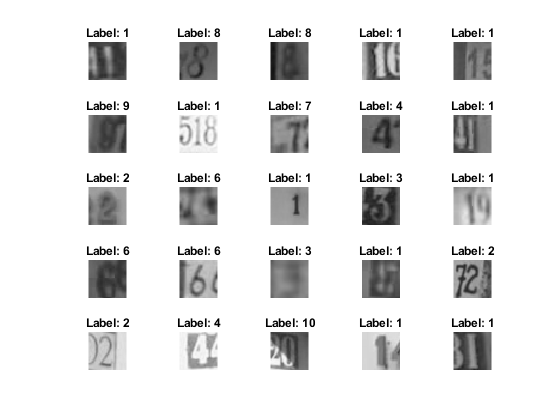

nWidth = 5;
nHeight = 5;

figure;
for ii = 1:nHeight*nWidth
    subplot(nHeight, nWidth, ii);
    randIndx = randi(size(x_train, 4));
    imshow(extractdata(x_train(:, :, :, randIndx)));
    title("Label: " + num2str(y_train(randIndx)));
end

### Build a DNN model

inputSize = size(x_train);
dnnLayers = [imageInputLayer(inputSize(1:end-1), "Name", "Input_Layer"), ...
    fullyConnectedLayer(512, "Name", "Dense_1", "WeightsInitializer", "glorot"), ...
    reluLayer("Name", "Relu_1"), ...
    fullyConnectedLayer(256, "Name", "Dense_2", "WeightsInitializer", "glorot"), ...
    reluLayer("Name", "Relu_2"), ...
    fullyConnectedLayer(128, "Name", "Dense_3", "WeightsInitializer", "glorot"), ...
    reluLayer("Name", "Relu_3"), ...
    fullyConnectedLayer(64, "Name", "Dense_4", "WeightsInitializer", "glorot"), ...
    reluLayer("Name", "Relu_4"), ...
    fullyConnectedLayer(32, "Name", "Dense_5", "WeightsInitializer", "glorot"), ...
    reluLayer("Name", "Relu_5"), ...
    fullyConnectedLayer(10, "Name", "Output_Layer"), ...
    softmaxLayer("Name", "Output_Softmax"), ...
    classificationLayer("Name", "Classification_Layer")];

opts = trainingOptions("adam", "Plots", "training-progress", ...
    "Verbose", true, "VerboseFrequency", 500, "MaxEpochs", 30, ...
    "MiniBatchSize", 512, "Shuffle", "every-epoch", "InitialLearnRate", 0.001, ...
    "LearnRateSchedule", "piecewise", "LearnRateDropPeriod", 10, "LearnRateDropFactor", 0.2);

net = trainNetwork(x_train, categorical(y_train), dnnLayers, opts);

Training on single GPU.
Initializing input data normalization.


|========================================================================================|
|  Epoch  |  Iteration  |  Time Elapsed  |  Mini-batch  |  Mini-batch  |  Base Learning  |
|         |             |   (hh:mm:ss)   |   Accuracy   |     Loss     |      Rate       |
|========================================================================================|


|       1 |           1 |       00:00:02 |        6.84% |       2.3103 |          0.0010 |


|       4 |         500 |       00:00:13 |       83.20% |       0.5160 |          0.0010 |


|       7 |        1000 |       00:00:24 |       85.74% |       0.4869 |          0.0010 |


|      11 |        1500 |       00:00:35 |       91.41% |       0.2595 |          0.0002 |


|      14 |        2000 |       00:00:45 |       91.41% |       0.2827 |          0.0002 |


|      18 |        2500 |       00:00:56 |       92.97% |       0.2028 |          0.0002 |


|      21 |        3000 |       00:01:07 |       94.53% |       0.2061 |      4.0000e-05 |


|      25 |        3500 |       00:01:18 |       94.73% |       0.1945 |      4.0000e-05 |


|      28 |        4000 |       00:01:29 |       93.55% |       0.2353 |      4.0000e-05 |


|      30 |        4290 |       00:01:35 |       96.48% |       0.1409 |      4.0000e-05 |
|========================================================================================|


function x = convRgb2Gray(x)
x = mean(x, 3);
end